## Discretization with real, complex and origin poles

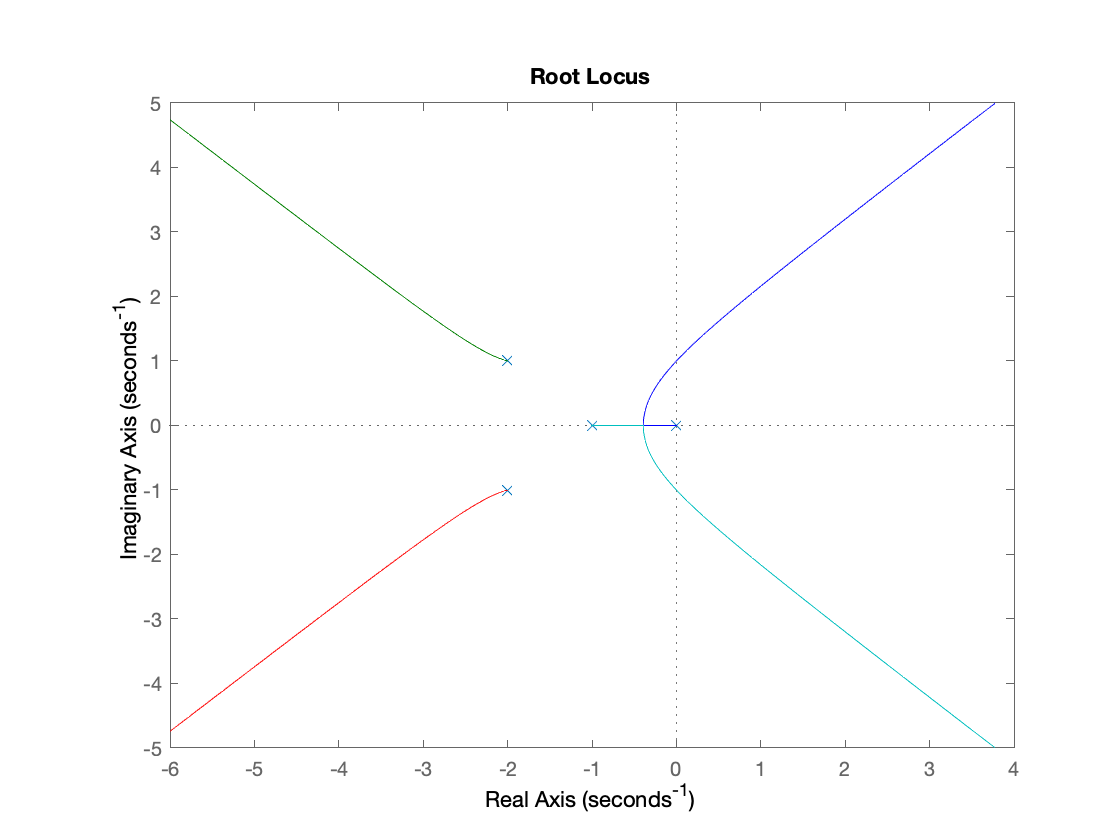

[A,B,C,D]=tf2ss(5,[1,5,9,5,0]); %System description
A;
B;
figure
rlocus(ss(A,B,C,D)) %Sytem poles representation

pole(ss(A,B,C,D));
T=2;
Td=T/40;

Continuous simulation:

Duty cycle $\delta$ to simulate the system with a sample time eighty times smaller thatn T in order to have a continuous response:

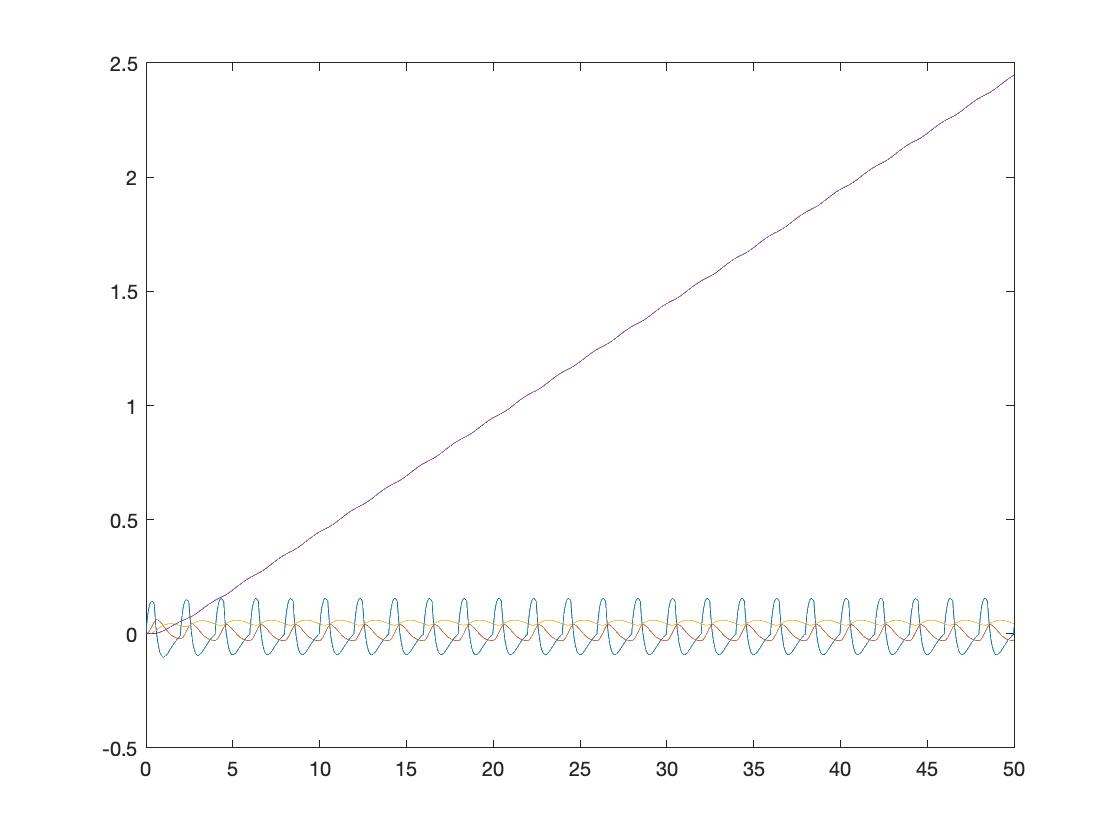

L=length(A);
Td=T/80;
N=50*80;
delta=0.25;
x=zeros(L,N);
x(:,1)=zeros(L,1);
for i=1:N+1
   if (mod(i,80)/80<0.25)
      x(:,i+1)=x(:,i)+Td*(A*x(:,i)+B);
   else
      x(:,i+1)=x(:,i)+ Td*A*x(:,i);
   end
end
figure
t=[0 (1:N+1)*Td];
plot(t,x') 
ylim([-0.5 2.5])
xlim([0 50])

Discrete simulation:

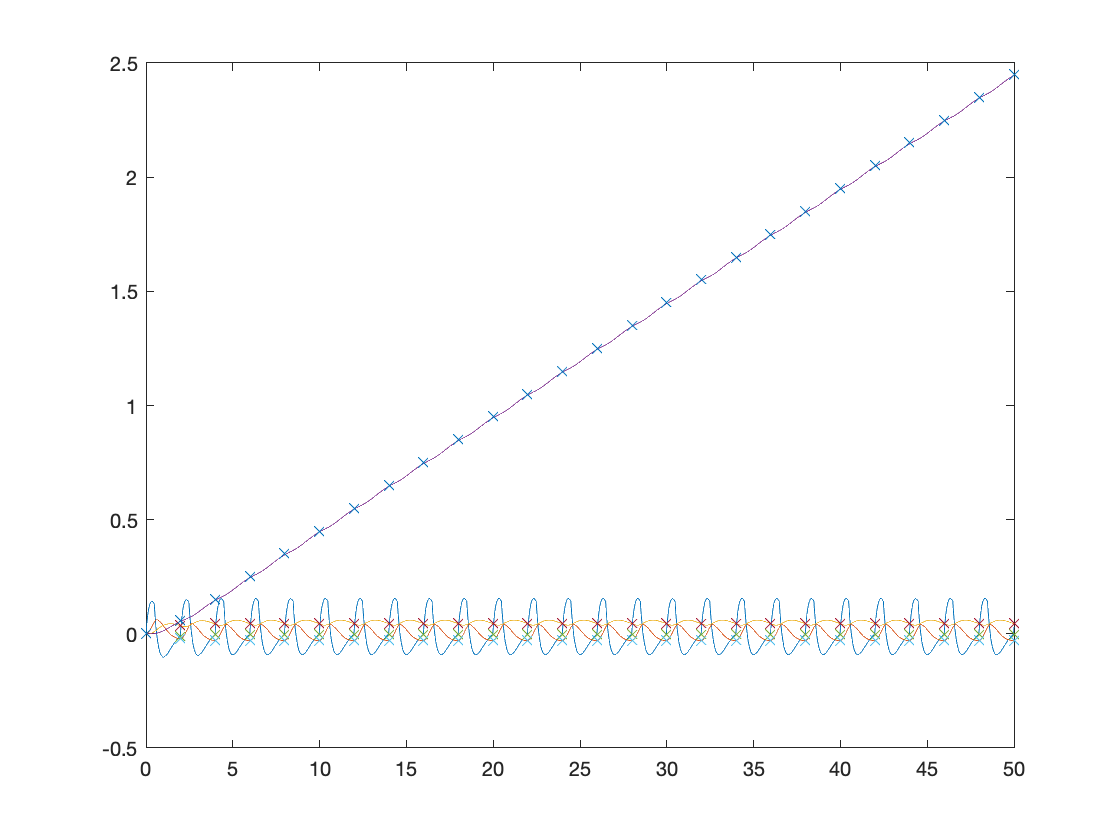

[PA,PB,alpha2]=discrete_binary_f(A,B,T);
delta=[0.25]; % Delta 1, the control action triggers the full duty cycle, 
%in this case, only triggers one fourth
N=50*20; %Number of cycles
x2=zeros(length(A),N);
x2(:,1)=zeros(L,1); %Initial state
alpha=[];
r=rank(A);
for j=1:length(alpha2)
    i=ceil(j/r);
    alpha=[alpha (1-alpha2{j}(delta(i))) alpha2{j}(delta(i))];
end
%Calculates each X value for each period of time.
for i=1:N+1
    x2(:,i+1)=PA*x2(:,i)+PB.eval(alpha)*delta';
end
figure
plot(t,x);
hold on
t2=[0 (1:N+1)*T];
plot(t2,x2','x')
ylim([-0.5 2.5])
xlim([0 50])

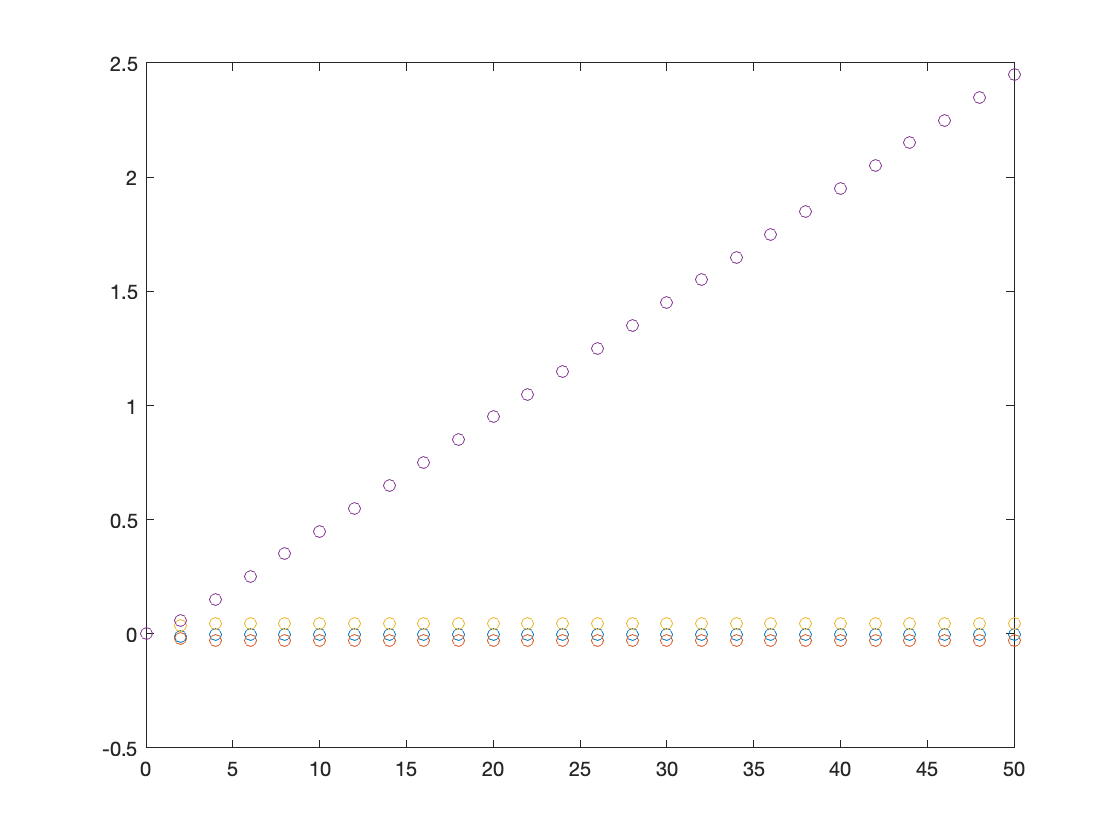

figure
plot(t2,x2','o')
ylim([-0.5 2.5])
xlim([0 50])